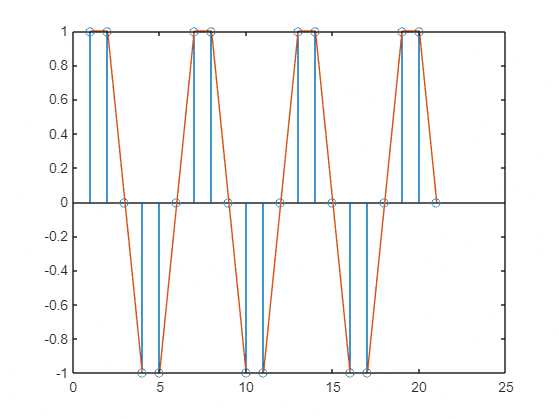

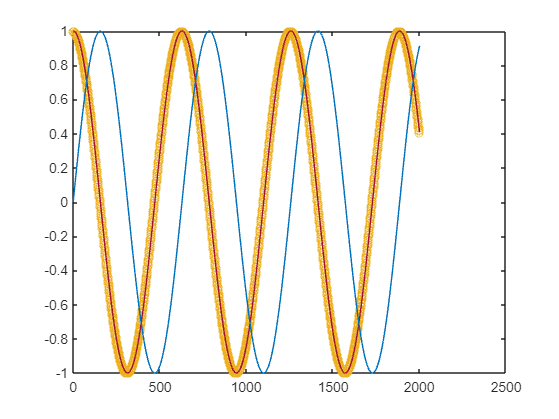

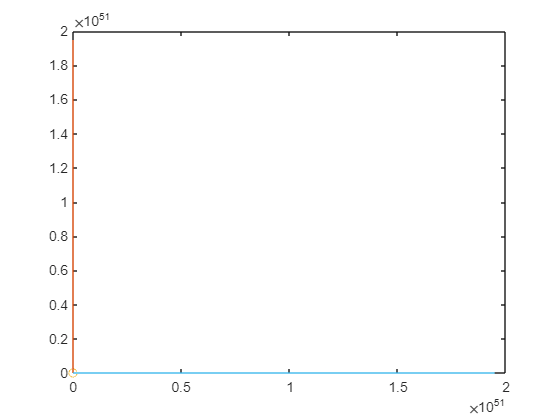

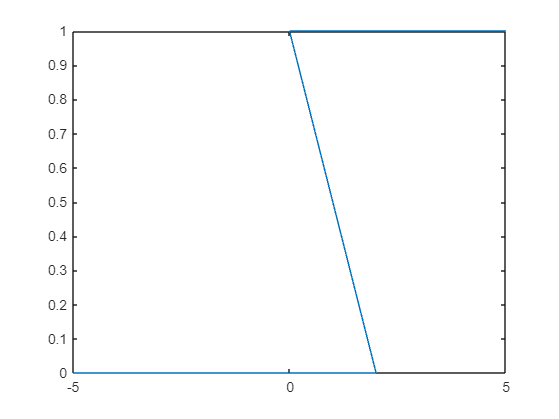

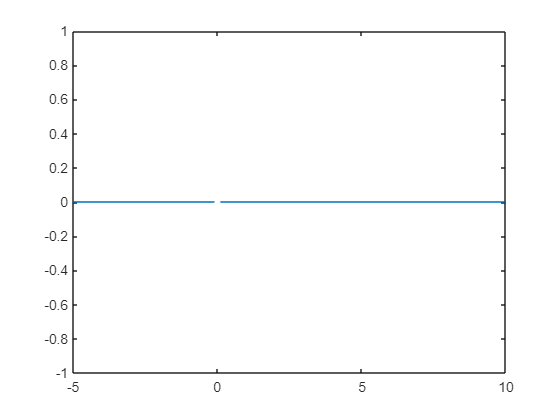

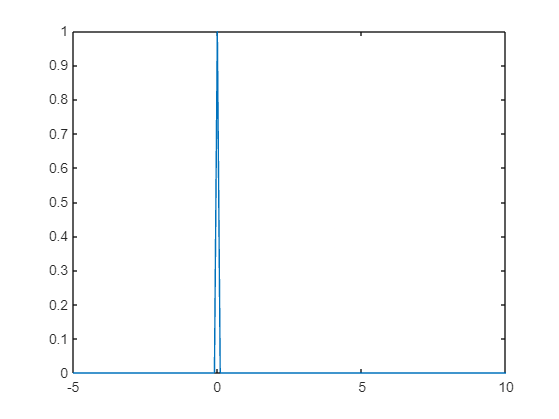

$$ans = t\in \mathbb{R}$$

$$d = \delta (t)$$

$$ans = 1$$

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


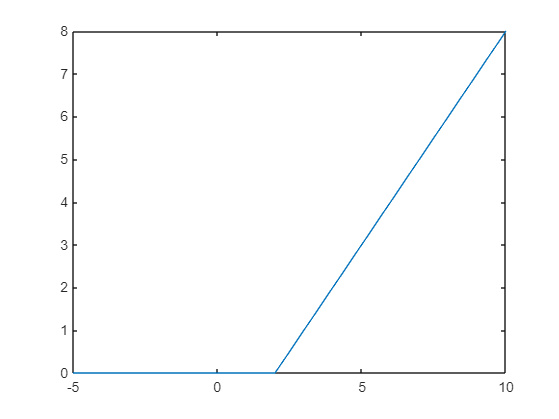

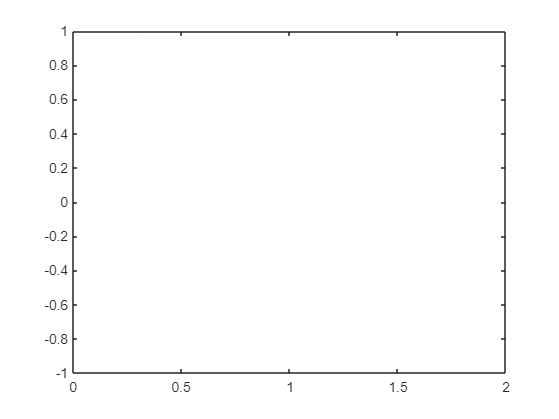

t = 0:1:20;

stem(round(cos(t))), hold on
plot(round(cos(t)))

for discrete , digital , cont signals

## Elementary Signals

Sinusoidal Wave

t= 0:0.05:4;
omega = 2*pi*t;
phi = pi/3;
x = 5*cos(omega+phi);
plot ( t,x)

t = 0:0.01:20;
plot(cos(t)),hold on
plot(sin(t))

t = -3:0.1:6;
x = 5*exp(0.4*t);
y = 3*exp(-0.9*t);
plot(t,x,t,y)

omega = pi;
phi = pi/3;
T = (2*pi)/omega;
t = 0:0.1:2;
y_re = real(2*exp(1j*pi*t)+ phi);
y_im = imag(2*exp(1j*pi*t)+ phi);

plot(t,y_re,t,y_im)

Unit Step Function

t = -2:0.1:5;
to = 2;
x = heaviside(t-to);
plot(t,x) %using heaviside
ylim([-0.2 1.2])

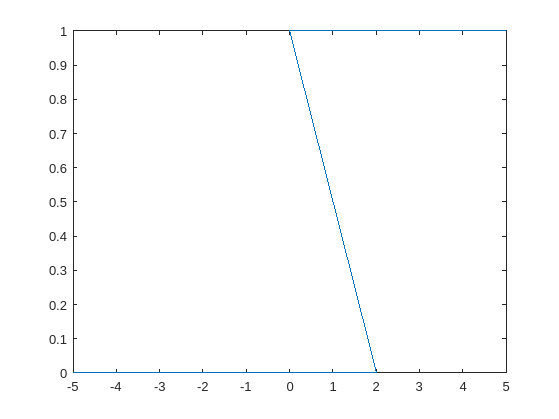

t = -5:0.1:2;
t1 = 0:0.1:5;

u1 = zeros(size(t));
u2 = ones(size(t1));

t = [t t1];
u = [u1 u2];

plot(t,u)

Unit impulse or Dirac Delta

t = -5:0.1:10;
d = dirac(t);
figure;
plot(t,d);

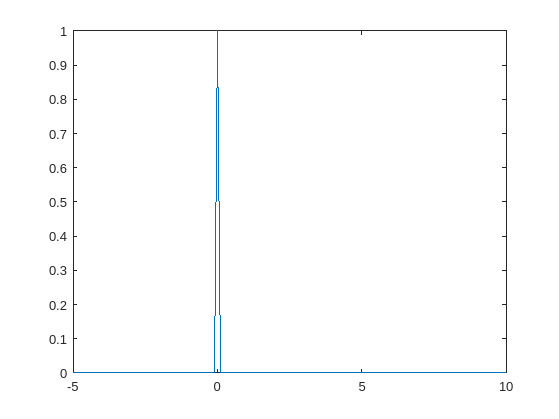

s = gauspuls(t);
plot(t,s);

Area under dirac delta is unity

syms t real
assumptions(t)

$$ans = t\in \mathbb{R}$$

d = dirac(t)

$$d = \delta (t)$$

int(d,t, -inf,inf)

$$ans = 1$$

Ramp Function

t = -5:0.1:10;
r = (t-2).*heaviside(t-2)

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


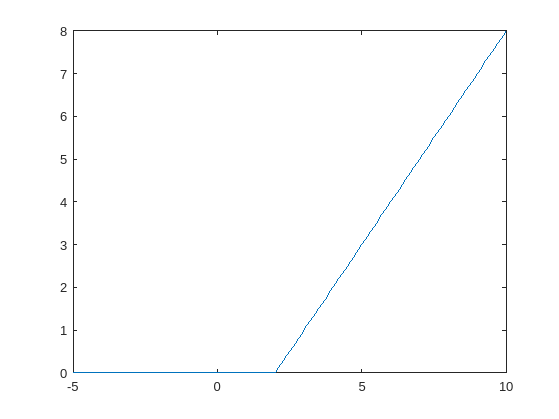

plot(t,r)

Rectangular Pulse

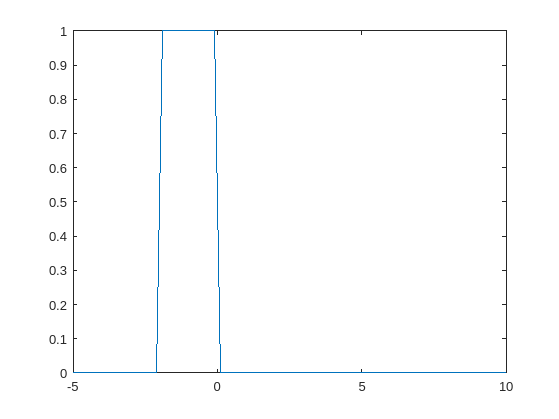

t = -5:0.1:10;
u1 = heaviside(t+2);
u2 = heaviside(t*2);
rect = u1-u2;
plot(t,rect)

Using inbuilt function

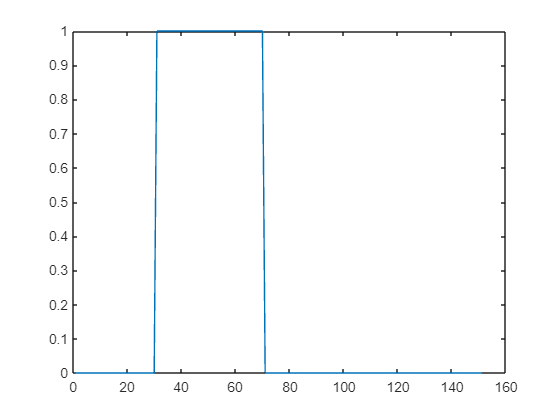

plot(rectpuls(t,4))

Signum Function

x = [-3 -eps(1) 0 eps(1) 3]

x =    -3.0000   -0.0000         0    0.0000    3.0000


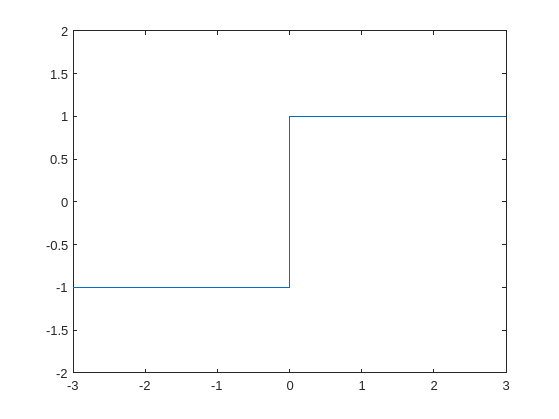

y = sign(x);
plot(x,y)
ylim([-2 2])

Unit Impulse Sequence

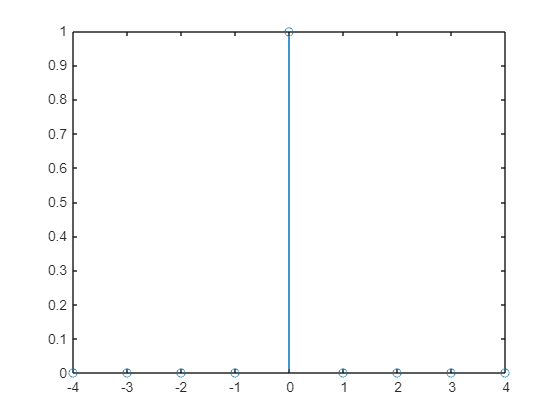

n = -4:4;
d = gauspuls(n);
stem(n,d);

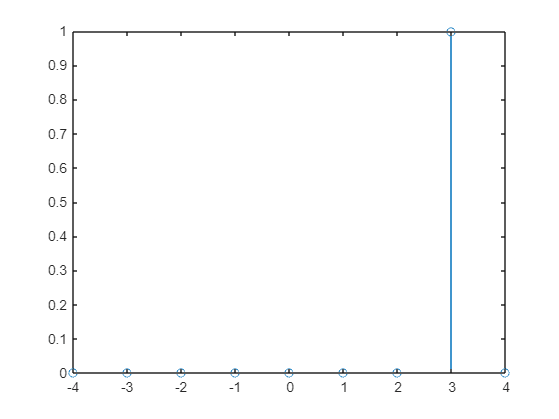

s = gauspuls(n-3);
stem(n,s);

Unit Impulse Sequence

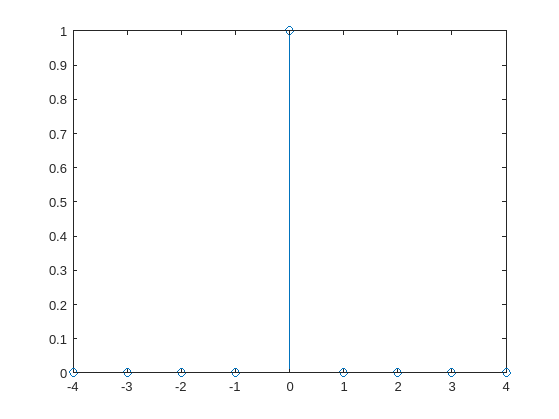

n1 = -3:0;
n2 = 0;
n3 = 0:3;
N=[n1 n2 n3];
d1 = zeros(size(n1));
d2 = 1;
d3 = zeros(size(n3));
d = [d1 d2 d3];
stem(n,d)

Another Way

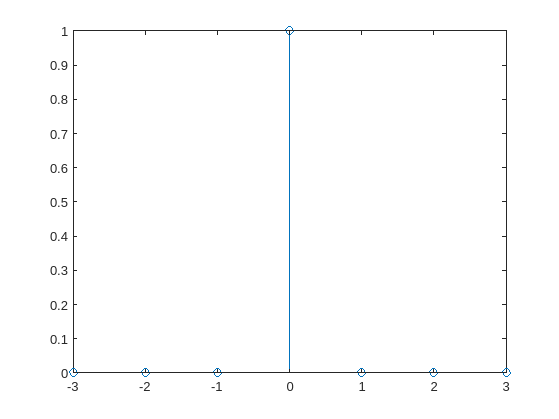

n = -3:3 ;
d =(n==0);
stem(n,d)

Unit Step Sequence

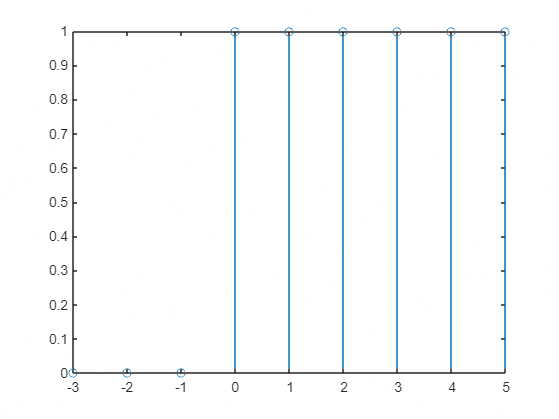

n = -3:5;
n0 = 0;
u = (n>= n0);
stem(n,u)

Real Exponential Sequence( increasing when mod(A) > 0 and decaying otherwise.

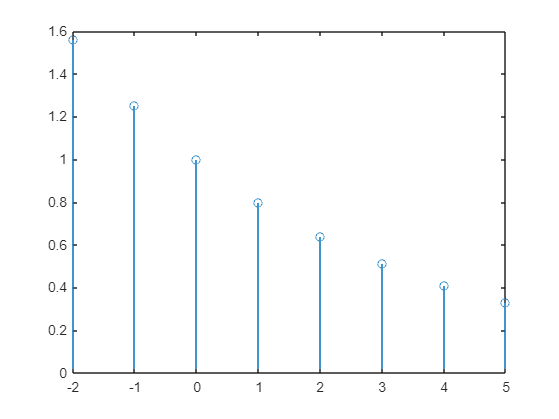

n = -2:5;
a1 = 0.8;
x1 = a1.^n;
stem(n,x1)

Complex Exonential Sequence

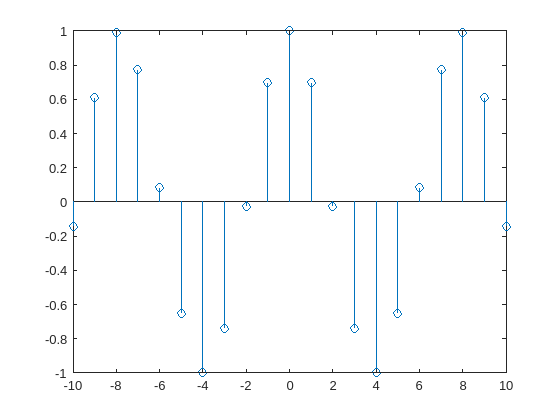

n = -10:10;
w = .8;
x = exp(1j*w*n);
stem(n,real(x));

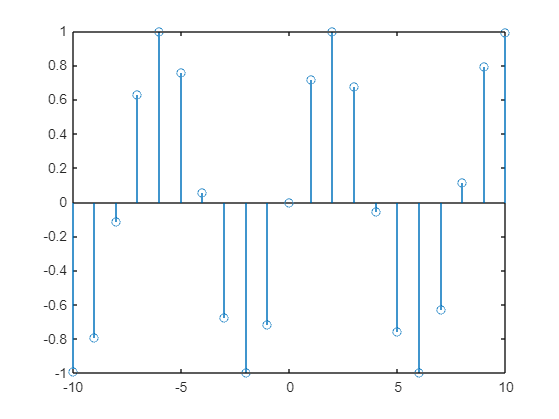

figure;
stem(n,imag(x));

Sinusoidal Sequence

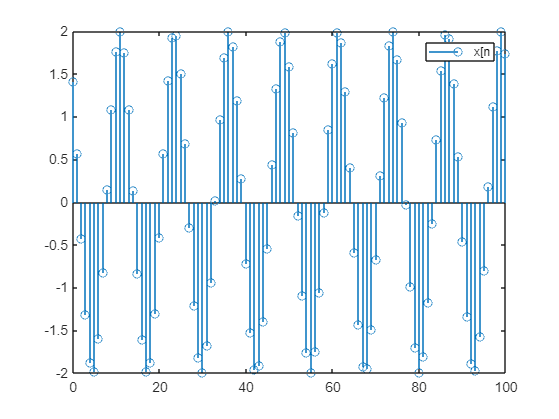

n = 0:100;
x = 2*cos(.5*n+pi/4);
stem(n,x)
legend('x[n')

with y

n = 0:100;
y = 2*cos(n*(pi/6)+pi/4)

y =     1.4142    0.5176   -0.5176   -1.4142   -1.9319   -1.9319   -1.4142   -0.5176    0.5176    1.4142    1.9319    1.9319    1.4142    0.5176   -0.5176   -1.4142   -1.9319   -1.9319   -1.4142   -0.5176    0.5176    1.4142    1.9319    1.9319    1.4142    0.5176   -0.5176   -1.4142   -1.9319   -1.9319   -1.4142   -0.5176    0.5176    1.4142    1.9319    1.9319    1.4142    0.5176   -0.5176   -1.4142   -1.9319   -1.9319   -1.4142   -0.5176    0.5176    1.4142    1.9319    1.9319    1.4142    0.5176


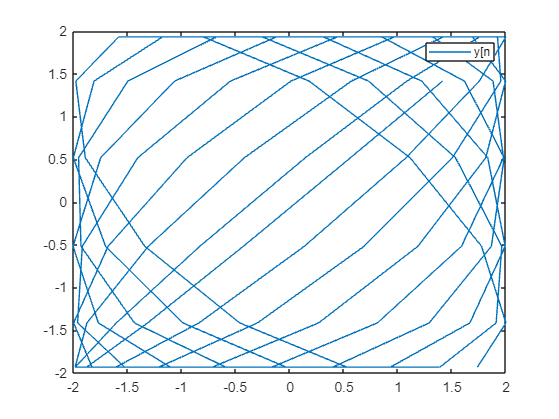

plot(x,y)
legend('y[n')